# Spike detection

Setup

a = arduino()

a =   arduino with properties:

                  Port: 'COM3'
                 Board: 'Uno'
         AvailablePins: {'D2-D13', 'A0-A5'}
  AvailableDigitalPins: {'D2-D13', 'A0-A5'}
      AvailablePWMPins: {'D3', 'D5-D6', 'D9-D11'}
   AvailableAnalogPins: {'A0-A5'}
    AvailableI2CBusIDs: [0]
             Libraries: {'I2C', 'SPI', 'Servo'}
Show all properties


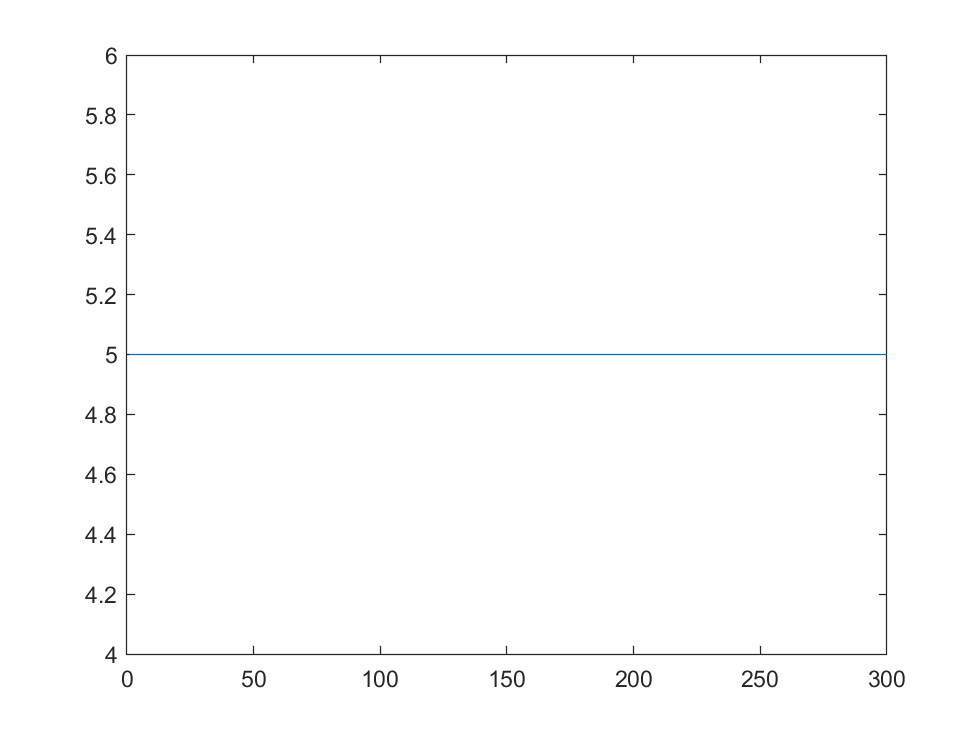


N = 300;
% s = 10*rand(N,1) + 100;
% spikeIndices = randi(N, [20, 1]);
% s(spikeIndices) = s(spikeIndices) - 50;

s = 5 * ones(N,1);

S = CircArray(s);
plot(s)


dt = 0.05 % seconds

dt = 0.0500

% S.RunningPlot(N)



% for tt = (0:2*pi/N:2*pi)
%     newInput = 300 + 100*sin(10*tt);
%     S.WriteVals(1, newInput);
%     S.RunningPlot(50)
%     drawnow;
%     pause(0.1)
% end


Threshold-based detection

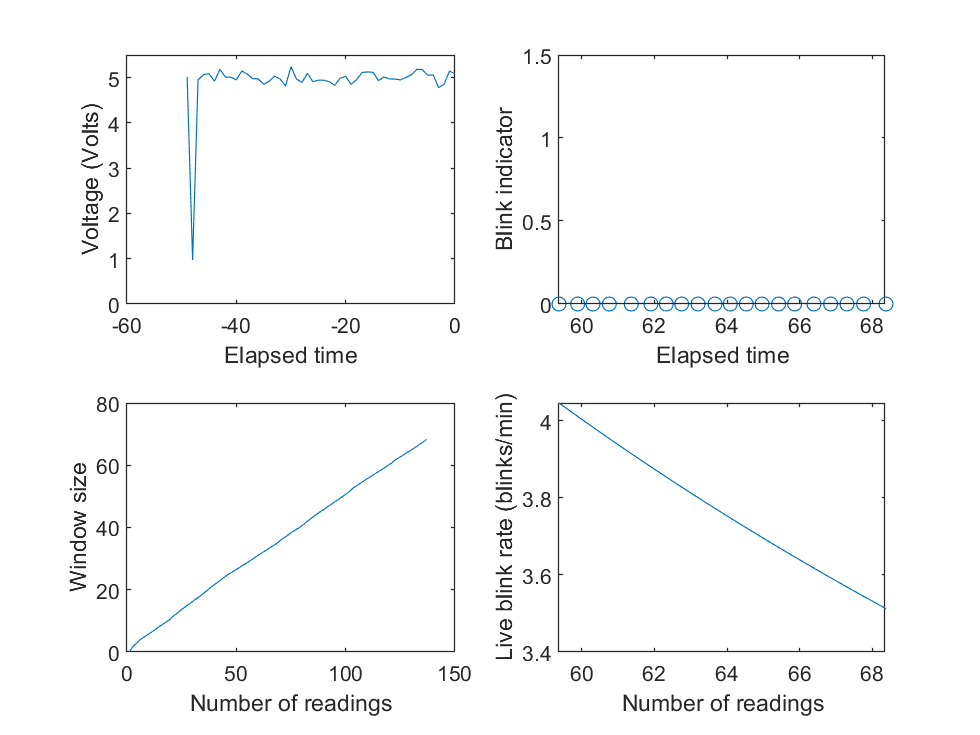

BUZZZZZZZZZZZZ


Blinks: 1


BUZZZZZZZZZZZZ


Blinks: 2


BUZZZZZZZZZZZZ


Blinks: 3


BUZZZZZZZZZZZZ


Blinks: 4


BUZZZZZZZZZZZZ


BUZZZZZZZZZZZZ


thresholdVal = 2.0; % Change to Volts
buzzerStuff = struct;
buzzerStuff.blinkRateThreshold = 10; % blinks per min
buzzerStuff.waitTime = 10; % s
buzzerStuff.timerRestart = true;
numConsecVals = 1;
trackBlinks = CircArray(zeros(N,1));

timeTrackingWindow = 30; % seconds 
slowingFactor = 4;
numTimeSteps = round(timeTrackingWindow/(slowingFactor*dt)); % note these will be only approximately realized

% trackTime = CircArray(zeros(numTimeSteps,1));
trackTime = CircArray((dt*(-numTimeSteps+1:0).'));

liveWindowSize = [];
liveBlinkRate = CircArray(zeros(N,1));

counter = 0;
blinkCounter = 0;
figure;
tic;

numTrack = 0;
while (toc<500)
    pause(dt)
    numTrack = numTrack + 1;
    tNow = toc;
    trackTime.WriteVals(1, tNow);
    %newInput = a.readVoltage('A0');
    newInput = 5 + 0.1*randn(1) - 4*(rand(1)>0.95); % state as assumption
    S.WriteVals(1, newInput);
    subplot(2,2,1)
    S.RunningTimePlot(trackTime, 20)
    S.RunningPlot(50);
    ylim([0,5.5])
    xlabel('Elapsed time')
    ylabel('Voltage (Volts)')
    
    
    if S.GetVals(0) < thresholdVal
        counter = counter + 1;
        trackBlinks.WriteVals(1,0);
    else
        if counter >= numConsecVals
            trackBlinks.WriteVals(1,1);
            blinkCounter = blinkCounter + 1;
            disp(['Blinks: ' num2str(blinkCounter)])
        else
            trackBlinks.WriteVals(1,0);
        end
        counter = 0;
    end
    subplot(2,2,2)
    trackBlinks.RunningTimeStem(trackTime, 20)
    ylim([0,1.5])
    xlabel('Elapsed time')
    ylabel('Blink indicator')
    %trackBlinks.RunningStem(50);
    if numTrack < numTimeSteps
        liveWindowSize = [liveWindowSize, trackTime.GetVals(0) - trackTime.GetVals(-numTrack+1)];
        liveBlinkRate.WriteVals(1, 60*sum(trackBlinks.GetVals((-numTrack+1):0))/liveWindowSize(end));
        
    else
        liveWindowSize = [liveWindowSize, trackTime.GetVals(0) - trackTime.GetVals(-numTimeSteps+1)];
        liveBlinkRate.WriteVals(1, 60*sum(trackBlinks.GetVals((-numTimeSteps+1):0))/liveWindowSize(end));
    end
    
    % Buzzer
    if liveBlinkRate.GetVals(0) < buzzerStuff.blinkRateThreshold
        if buzzerStuff.timerRestart
            startTime = toc;
        end
        
        checkTime = toc - startTime;
        if checkTime > buzzerStuff.waitTime
            disp('BUZZZZZZZZZZZZ')
            a.playTone('D5',2400,1);
            buzzerStuff.timerRestart = true;
        else
            buzzerStuff.timerRestart = false;
        end
        
    end
    
    subplot(2,2,3);
    %trackTime.RunningPlot(50)
    plot(liveWindowSize)
    xlabel('Number of readings')
    ylabel('Window size')
    subplot(2,2,4);
    liveBlinkRate.RunningTimePlot(trackTime, 20)
    xlabel('Number of readings')
    ylabel('Live blink rate (blinks/min)')
    drawnow;
end

-- Double blink

-- Timer and constant rate: 5s/blink, 10s/blink

% stem(trackBlinks.Data)

Buzzer indicator

Deviation of the signal from its running average

windowLength = 21;
sSmooth = movmean(s,windowLength);
figure;
plot((1:N).', s, (1:N).',sSmooth)
figure;
plot(s-sSmooth);

